[XTrain,YTrain,anglesTrain] = streak4DTrainArrayData(512);

dsXTrain = arrayDatastore(XTrain,'IterationDimension',4);
dsYTrain = arrayDatastore(YTrain);
dsAnglesTrain = arrayDatastore(anglesTrain);

dsTrain = combine(dsXTrain,dsYTrain,dsAnglesTrain);

classNames = categories(YTrain);
numClasses = numel(classNames);
numObservations = numel(YTrain);

classNames

classNames = 47×1 cell array
    {'0' }
    {'1' }
    {'2' }
    {'3' }
    {'4' }
    {'5' }
    {'6' }
    {'7' }
    {'8' }
    {'9' }
    {'10'}
    {'11'}
    {'12'}
    {'13'}
    {'14'}
    {'15'}
    {'16'}
    {'17'}
    {'18'}
    {'19'}
    {'20'}
    {'21'}
    {'22'}
    {'23'}
    {'24'}
    {'25'}
    {'26'}
    {'27'}
    {'28'}
    {'30'}


numClasses

numClasses = 47

numObservations

numObservations = 256

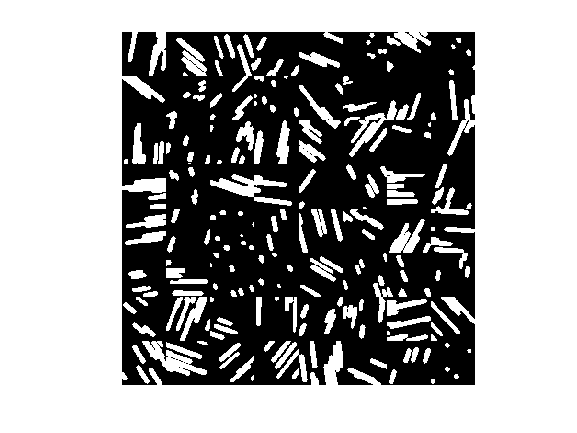

idx = randperm(numObservations,64);
I = imtile(XTrain(:,:,:,idx));
figure
imshow(I)

layers = [
    imageInputLayer([48 48 1],'Normalization','none','Name','in')
    
    convolution2dLayer(5,8,'Padding','same','Name','conv1')
    batchNormalizationLayer('Name','bn1')
    reluLayer('Name','relu1')
    
    convolution2dLayer(5,16,'Padding','same','Stride',2,'Name','conv2')
    batchNormalizationLayer('Name','bn2')
    reluLayer('Name','relu2')
    
    convolution2dLayer(5,32,'Padding','same','Name','conv3')
    batchNormalizationLayer('Name','bn3')
    reluLayer('Name','relu4')

    additionLayer(2,'Name','addition')
    
    fullyConnectedLayer(numClasses,'Name','fc1')
    softmaxLayer('Name','softmax')];

lgraph = layerGraph(layers);

layers = [
    convolution2dLayer(1,32,'Stride',2,'Name','convSkip')
    batchNormalizationLayer('Name','bnSkip')
    reluLayer('Name','reluSkip')];

lgraph = addLayers(lgraph,layers);
lgraph = connectLayers(lgraph,'relu1','convSkip');
lgraph = connectLayers(lgraph,'reluSkip','addition/in2');

layers = fullyConnectedLayer(1,'Name','fc2');
lgraph = addLayers(lgraph,layers);
lgraph = connectLayers(lgraph,'addition','fc2');

% layers = [
%     imageInputLayer([48 48 1], 'Normalization','none', 'Name', 'input')
%     
%     convolution2dLayer(5,8,'Padding','same', 'Name', 'conv1')
%     reluLayer('Name', 'relu1')
%     averagePooling2dLayer(2,'Stride',2, 'Name', 'pool1')
%     
%     batchNormalizationLayer('Name', 'bn1')
%     
%     
%     convolution2dLayer(5,16,'Padding','same', 'Name', 'conv2')
%     reluLayer('Name', 'relu2')
%     averagePooling2dLayer(2,'Stride',2, 'Name', 'pool2')
%     
%     batchNormalizationLayer('Name', 'bn2')
%     
%     
%     convolution2dLayer(5,32,'Padding','same', 'Name', 'conv3')
%     reluLayer('Name', 'relu3')
%     averagePooling2dLayer(2,'Stride',2, 'Name', 'pool3')
%     
%     batchNormalizationLayer('Name', 'bn3')
%     
%     convolution2dLayer(5,32,'Padding','same', 'Name', 'conv4')
%     reluLayer('Name', 'relu4')
%     averagePooling2dLayer(2,'Stride',2, 'Name', 'pool4')
%     
%     batchNormalizationLayer('Name', 'bn4')
%     
% %     additionLayer(2,'Name','addition')
%     
%     dropoutLayer(0.3, 'Name', 'drop')
%     
%     fullyConnectedLayer(31, 'Name', 'fc1')
%     softmaxLayer('Name', 'softmax1')
% ];
% lgraph = layerGraph(layers);

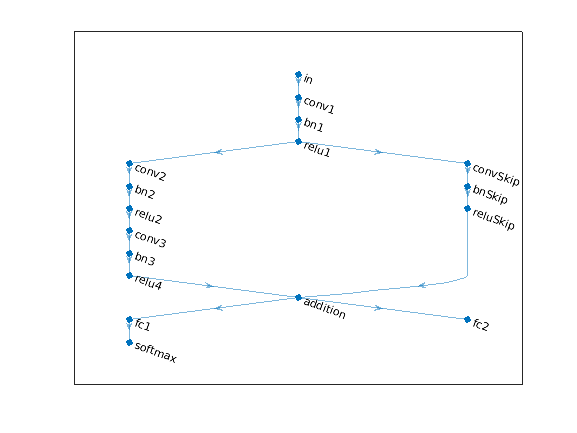

figure
plot(lgraph)

dlnet = dlnetwork(lgraph)

dlnet =   dlnetwork with properties:

         Layers: [17×1 nnet.cnn.layer.Layer]
    Connections: [17×2 table]
     Learnables: [20×3 table]
          State: [8×3 table]
     InputNames: {'in'}
    OutputNames: {'softmax'  'fc2'}
    Initialized: 1


numEpochs = 100;
miniBatchSize = 64;
plots = "training-progress";

mbq = minibatchqueue(dsTrain,...
    'MiniBatchSize',miniBatchSize,...
    'MiniBatchFcn', @preprocessData,...
    'MiniBatchFormat',{'SSCB','',''});

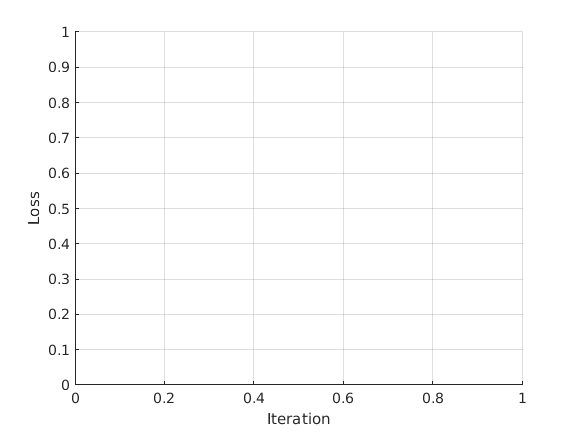

if plots == "training-progress"
    figure
    lineLossTrain = animatedline('Color',[0.85 0.325 0.098]);
    ylim([0 inf])
    xlabel("Iteration")
    ylabel("Loss")
    grid on
end

trailingAvg = [];
trailingAvgSq = [];

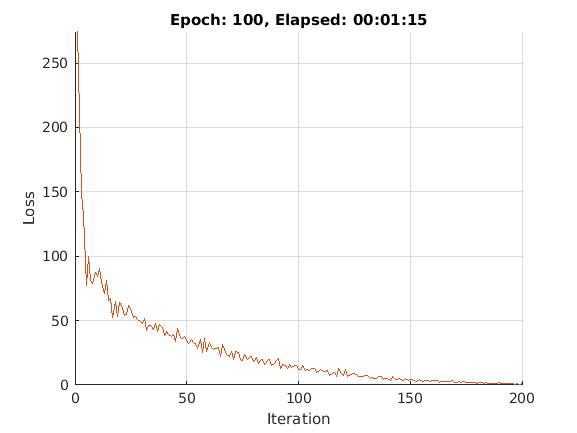

iteration = 0;
start = tic;

% Loop over epochs.
for epoch = 1:numEpochs
    
    % Shuffle data.
    shuffle(mbq)
    
    % Loop over mini-batches
    while hasdata(mbq)
        
        iteration = iteration + 1;
        
        [dlX,dlY1,dlY2] = next(mbq);
                       
        % Evaluate the model gradients, state, and loss using dlfeval and the
        % modelGradients function.
        [gradients,state,loss] = dlfeval(@modelGradients, dlnet, dlX, dlY1, dlY2);
        dlnet.State = state;
        
        % Update the network parameters using the Adam optimizer.
        [dlnet,trailingAvg,trailingAvgSq] = adamupdate(dlnet,gradients, ...
            trailingAvg,trailingAvgSq,iteration);
        
        % Display the training progress.
        if plots == "training-progress"
            D = duration(0,0,toc(start),'Format','hh:mm:ss');
            addpoints(lineLossTrain,iteration,double(gather(extractdata(loss))))
            title("Epoch: " + epoch + ", Elapsed: " + string(D))
            drawnow
        end
    end
end

[XTest,Y1Test,anglesTest] = streak4DTestArrayData(512);

dsXTest = arrayDatastore(XTest,'IterationDimension',4);
dsYTest = arrayDatastore(Y1Test);
dsAnglesTest = arrayDatastore(anglesTest);

dsTest = combine(dsXTest,dsYTest,dsAnglesTest);

mbqTest = minibatchqueue(dsTest,...
    'MiniBatchSize',miniBatchSize,...
    'MiniBatchFcn', @preprocessData,...
    'MiniBatchFormat',{'SSCB','',''});

classesPredictions = [];
anglesPredictions = [];
classCorr = [];
angleDiff = [];

testclassNames = categories(Y1Test);
testnumClasses = numel(classNames);
testnumObservations = numel(Y1Test);

testclassNames

testclassNames = 44×1 cell array
    {'0' }
    {'1' }
    {'2' }
    {'3' }
    {'4' }
    {'5' }
    {'6' }
    {'8' }
    {'9' }
    {'10'}
    {'11'}
    {'12'}
    {'13'}
    {'14'}
    {'15'}
    {'16'}
    {'17'}
    {'18'}
    {'19'}
    {'20'}
    {'21'}
    {'22'}
    {'23'}
    {'24'}
    {'25'}
    {'26'}
    {'27'}
    {'28'}
    {'29'}
    {'30'}


testnumClasses

testnumClasses = 47

testnumObservations

testnumObservations = 128

% Loop over mini-batches.
while hasdata(mbqTest)
    
    % Read mini-batch of data.
    [dlXTest,dlY1Test,dlY2Test] = next(mbqTest);
    
    % Make predictions using the predict function.
    [dlY1Pred,dlY2Pred] = predict(dlnet,dlXTest,'Outputs',["softmax" "fc2"]);
    
    % Determine predicted classes.
    Y1PredBatch = onehotdecode(dlY1Pred,classNames,1);
    classesPredictions = [classesPredictions Y1PredBatch];
    
    % Dermine predicted angles
    Y2PredBatch = extractdata(dlY2Pred);
    anglesPredictions = [anglesPredictions Y2PredBatch];
    
    % Compare predicted and true classes
    Y1Test = onehotdecode(dlY1Test,classNames,1);
    classCorr = [classCorr Y1PredBatch == Y1Test];
    
    % Compare predicted and true angles
    angleDiffBatch = Y2PredBatch - dlY2Test;
    angleDiff = [angleDiff extractdata(gather(angleDiffBatch))];
    
end

Error using onehotdecode (line 54)
Size of dimension 1 must be the same as the number of classes.

Error in dlarray/onehotdecode (line 44)
A = onehotdecode(extractdata(B),classes,featdim,typename);

accuracy = mean(classCorr)

accuracy = NaN

angleRMSE = sqrt(mean(angleDiff.^2))

angleRMSE = NaN

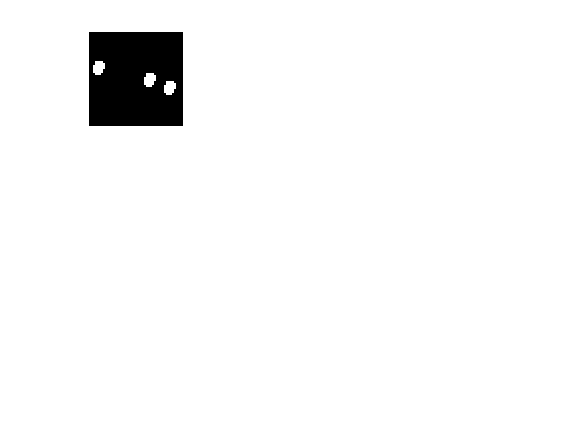

Index exceeds the number of array elements (0).

idx = randperm(size(XTest,4),9);
figure
for i = 1:9
    subplot(3,3,i)
    I = XTest(:,:,:,idx(i));
    imshow(I)
    hold on
    
    sz = size(I,1);
    offset = sz/2;
    
    thetaPred = anglesPredictions(idx(i));
    plot(offset*[1-tand(thetaPred) 1+tand(thetaPred)],[sz 0],'r--')
    
    thetaValidation = anglesTest(idx(i));
    plot(offset*[1-tand(thetaValidation) 1+tand(thetaValidation)],[sz 0],'g--')
    
    hold off
    label = string(classesPredictions(idx(i)));
    title("Label: " + label)
end